% General parameter

Tw_awu = ts_5/5;

Unrecognized function or variable 'ts_5'.

Kw_awu = 1/Tw_awu;


## step 50 [deg] simulations


% simulate value with no antiwindup filter step 50 [deg] 

step_amplitude = 50;

data = sim("lab3_windup_sim.slx");

t = data.ScopeData1.time;
tetha = data.ScopeData1.signals(1).values;  
ref = data.ScopeData1.signals(2).values;
error = data.ScopeData1.signals(3).values;
command_u =  data.ScopeData1.signals(4).values;

save("windup_data_lab3_50.mat",'t','tetha','ref','error','command_u');


% simulation antiwindup step 50 [deg]

data1 = sim("lab3_antiwindup_sim.slx");

t1 = data1.ScopeData1.time;
tetha1 = data1.ScopeData1.signals(1).values;  
ref1 = data1.ScopeData1.signals(2).values;
error1 = data1.ScopeData1.signals(3).values;
command_u1 =  data1.ScopeData1.signals(4).values;

save("antiwindup_data_lab3_50.mat",'t1','tetha1','ref1','error1','command_u1');

## step 120 [deg] simulations


% simulate value with no antiwindup filter step 50 [deg] 

step_amplitude = 120;

data2 = sim("lab3_windup_sim.slx");

t2 = data2.ScopeData1.time;
tetha2 = data2.ScopeData1.signals(1).values;  
ref2 = data2.ScopeData1.signals(2).values;
error2 = data2.ScopeData1.signals(3).values;
command_u2 =  data2.ScopeData1.signals(4).values;

save("windup_data_lab3_120.mat",'t2','tetha2','ref2','error2','command_u2');


% simulation antiwindup step 120 [deg]

data3 = sim("lab3_antiwindup_sim.slx");

t3 = data3.ScopeData1.time;
tetha3 = data3.ScopeData1.signals(1).values;  
ref3 = data3.ScopeData1.signals(2).values;
error3 = data3.ScopeData1.signals(3).values;
command_u3 =  data3.ScopeData1.signals(4).values;

save("antiwindup_data_lab3_120.mat",'t1','tetha1','ref1','error1','command_u1');


## Stampa grafici

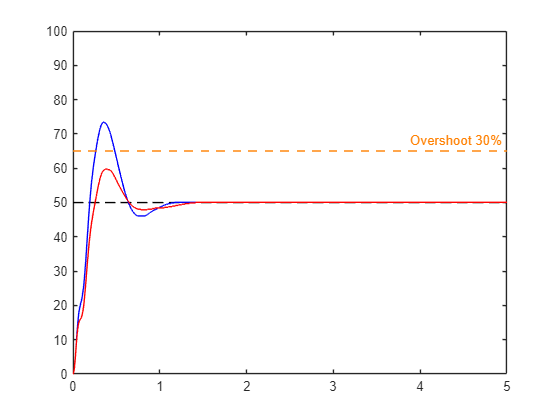


% grafico step 50 deg

load("windup_data_lab3_50.mat");
load("antiwindup_data_lab3_50.mat");
figure;
plot(t,ref,'k--');
yline(65, '--', 'Color', '[1, 0.5, 0]', 'LineWidth', 1.5, 'Label', 'Overshoot 30%');
hold on 
plot(t,tetha,'b');
plot(t1,tetha1,'r');
axis([0 5 0 100])
hold off

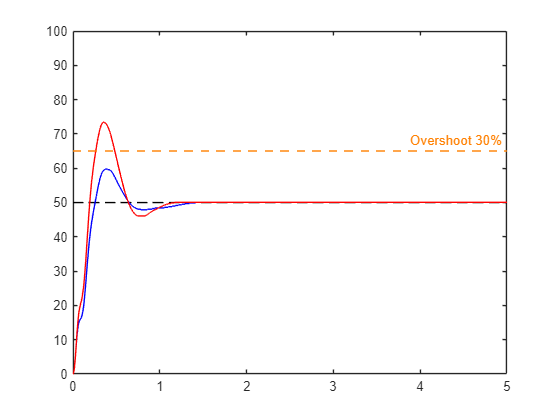



load("windup_data_lab3_120.mat");
load("antiwindup_data_lab3_120.mat");
figure;
plot(t2,ref2,'k--');
yline(65, '--', 'Color', '[1, 0.5, 0]', 'LineWidth', 1.5, 'Label', 'Overshoot 30%');
hold on 
plot(t1,tetha1,'b');
plot(t2,tetha2,'r');
axis([0 5 0 100])
hold off

#### Step response parameters

% Calcolo dei dati mantenendo i tuoi nomi originali
step_50_wind_up = stepinfo(tetha, t, 50, 'SettlingTimeThreshold', 0.05);
step_50_anti_wind_up = stepinfo(tetha1, t1, 50, 'SettlingTimeThreshold', 0.05);
step_120_wind_up = stepinfo(tetha2, t2, 120, 'SettlingTimeThreshold', 0.05);
step_120_anti_wind_up = stepinfo(tetha3, t3, 120, 'SettlingTimeThreshold', 0.05);

% Raccolta dei risultati in un array di strutture
results = [step_50_wind_up; step_50_anti_wind_up; step_120_wind_up; step_120_anti_wind_up];

% Conversione in tabella
T = struct2table(results);

% Aggiunta dei nomi delle righe per chiarezza
T.Properties.RowNames = {
    'step_50_wind_up', ...
    'step_50_anti_wind_up', ...
    'step_120_wind_up', ...
    'step_120_anti_wind_up'
};

% Visualizzazione della tabella

disp(T(:, {'RiseTime', 'SettlingTime', 'Overshoot'}))
